clc
clear
close all

% Carregar dados
out_nowind = load("./sims/sim_nowind.mat").out;
out_wind10_2s = load("./sims/sim_wind10_2s.mat").out;
out_wind10_5s = load("./sims/sim_wind10_5s.mat").out;
out_wind20_2s = load("./sims/sim_wind20_2s.mat").out;
out_wind20_5s = load("./sims/sim_wind20_5s.mat").out;


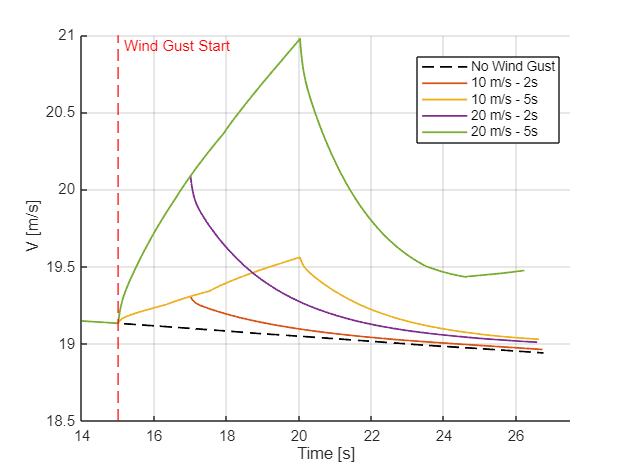

figure(); hold on
plot(out_nowind.main_clock, -out_nowind.vehicle_velocity(:, 3), 'k--', 'LineWidth', 1.2, 'DisplayName', 'No Wind Gust')
plot(out_wind10_2s.main_clock, -out_wind10_2s.vehicle_velocity(:, 3), 'LineWidth', 1.2, 'DisplayName', '10 m/s - 2s')
plot(out_wind10_5s.main_clock, -out_wind10_5s.vehicle_velocity(:, 3), 'LineWidth', 1.2, 'DisplayName', '10 m/s - 5s')
plot(out_wind20_2s.main_clock, -out_wind20_2s.vehicle_velocity(:, 3), 'LineWidth', 1.2, 'DisplayName', '20 m/s - 2s')
plot(out_wind20_5s.main_clock, -out_wind20_5s.vehicle_velocity(:, 3), 'LineWidth', 1.2, 'DisplayName', '20 m/s - 5s')
legend("Location", "best")
xlabel("Time [s]")
ylabel(" V [m/s]")  % ou  se for velocidade vertical
xlim([14 27.5])
xline(15, '--r', 'Wind Gust Start', 'LabelOrientation', 'horizontal', ...
      'LabelVerticalAlignment', 'top', 'HandleVisibility', 'off','LineWidth',1.2)
grid on;
set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'wind_velocity_z_comp', '-depsc')  % EPS a cores

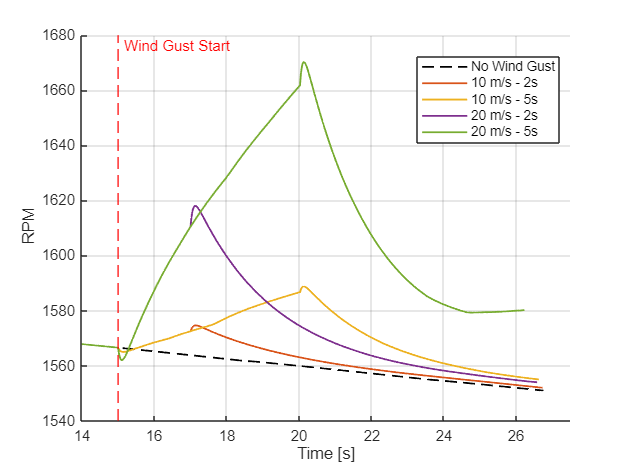


figure(); hold on
plot(out_nowind.main_clock, out_nowind.rotor_rpm, 'k--', 'LineWidth', 1.2, 'DisplayName', 'No Wind Gust')
plot(out_wind10_2s.main_clock, out_wind10_2s.rotor_rpm, 'LineWidth', 1.2, 'DisplayName', '10 m/s - 2s')
plot(out_wind10_5s.main_clock, out_wind10_5s.rotor_rpm, 'LineWidth', 1.2, 'DisplayName', '10 m/s - 5s')
plot(out_wind20_2s.main_clock, out_wind20_2s.rotor_rpm, 'LineWidth', 1.2, 'DisplayName', '20 m/s - 2s')
plot(out_wind20_5s.main_clock, out_wind20_5s.rotor_rpm, 'LineWidth', 1.2, 'DisplayName', '20 m/s - 5s')
legend("Location", "best")
xlabel("Time [s]")
ylabel(" RPM")
xlim([14 27.5])
xline(15, '--r', 'Wind Gust Start', 'LabelOrientation', 'horizontal', ...
      'LabelVerticalAlignment', 'top', 'HandleVisibility', 'off','LineWidth',1.2)
grid on;
set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'wind_rotor_velocity_comp', '-depsc')  % EPS a cores

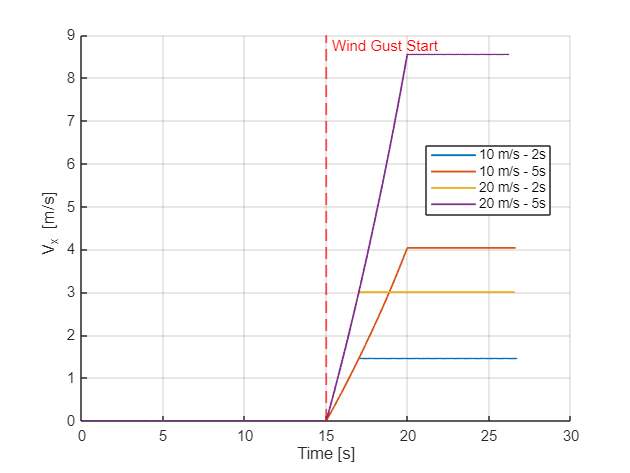

figure(); hold on
plot(out_wind10_2s.main_clock, out_wind10_2s.vehicle_velocity(:, 1), 'LineWidth', 1.2, 'DisplayName', '10 m/s - 2s')
plot(out_wind10_5s.main_clock, out_wind10_5s.vehicle_velocity(:, 1), 'LineWidth', 1.2, 'DisplayName', '10 m/s - 5s')
plot(out_wind20_2s.main_clock, out_wind20_2s.vehicle_velocity(:, 1), 'LineWidth', 1.2, 'DisplayName', '20 m/s - 2s')
plot(out_wind20_5s.main_clock, out_wind20_5s.vehicle_velocity(:, 1), 'LineWidth', 1.2, 'DisplayName', '20 m/s - 5s')
legend("Location", "best")
xlabel("Time [s]")
ylabel(" V_x [m/s]")  % ou  se for velocidade vertical
xline(15, '--r', 'Wind Gust Start', 'LabelOrientation', 'horizontal', ...
      'LabelVerticalAlignment', 'top', 'HandleVisibility', 'off','LineWidth',1.2)
grid on;
set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'wind_velocity_x_comp', '-depsc')  % EPS a cores

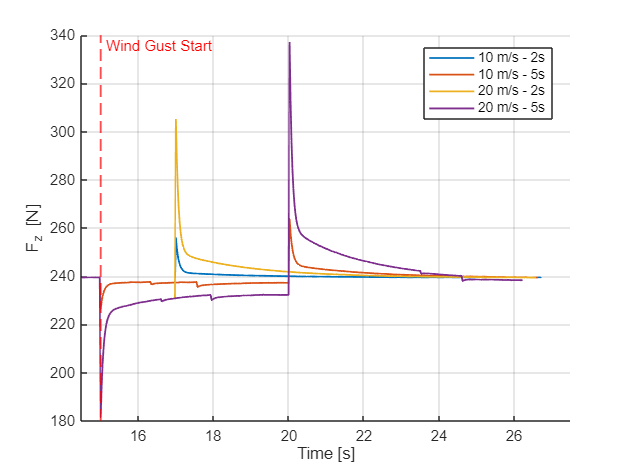

% Posição
figure(); hold on
plot(out_wind10_2s.main_clock, out_wind10_2s.F_rotor(:, 3), 'LineWidth', 1.2, 'DisplayName', '10 m/s - 2s')
plot(out_wind10_5s.main_clock, out_wind10_5s.F_rotor(:, 3), 'LineWidth', 1.2, 'DisplayName', '10 m/s - 5s')
plot(out_wind20_2s.main_clock, out_wind20_2s.F_rotor(:, 3), 'LineWidth', 1.2, 'DisplayName', '20 m/s - 2s')
plot(out_wind20_5s.main_clock, out_wind20_5s.F_rotor(:, 3), 'LineWidth', 1.2, 'DisplayName', '20 m/s - 5s')
legend("Location", "best")
xlabel("Time [s]")
ylabel("F_z [N]")  % ou  se for velocidade vertical
xlim([14.5 27.5])
xline(15, '--r', 'Wind Gust Start', 'LabelOrientation', 'horizontal', ...
      'LabelVerticalAlignment', 'top', 'HandleVisibility', 'off','LineWidth',1.2)
grid on;
set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'wind_force_z_comp', '-depsc')  % EPS a cores

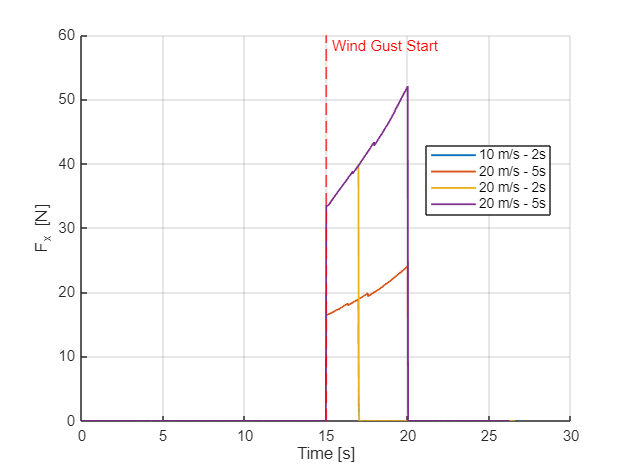


figure(); hold on
plot(out_wind10_2s.main_clock, out_wind10_2s.F_rotor(:, 1), 'LineWidth', 1.2, 'DisplayName', '10 m/s - 2s')
plot(out_wind10_5s.main_clock, out_wind10_5s.F_rotor(:, 1), 'LineWidth', 1.2, 'DisplayName', '20 m/s - 5s')
plot(out_wind20_2s.main_clock, out_wind20_2s.F_rotor(:, 1), 'LineWidth', 1.2, 'DisplayName', '20 m/s - 2s')
plot(out_wind20_5s.main_clock, out_wind20_5s.F_rotor(:, 1), 'LineWidth', 1.2, 'DisplayName', '20 m/s - 5s')
legend("Location", "best")
xlabel("Time [s]")
ylabel("F_x [N]") 
xline(15, '--r', 'Wind Gust Start', 'LabelOrientation', 'horizontal', ...
      'LabelVerticalAlignment', 'top', 'HandleVisibility', 'off','LineWidth',1.2)
grid on;
set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'wind_force_x_comp', '-depsc')  % EPS a cores

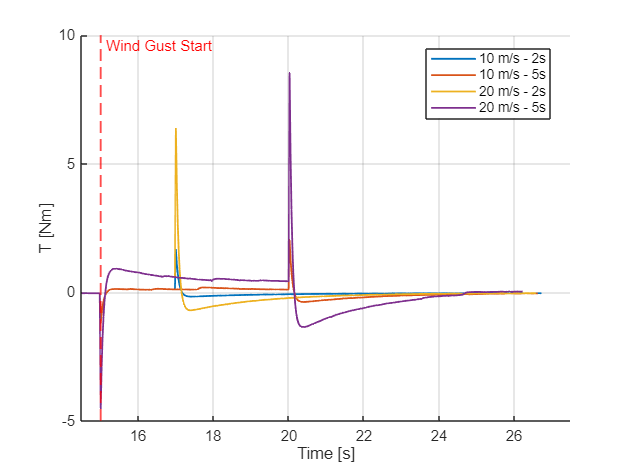

% Posição
figure(); hold on
plot(out_wind10_2s.main_clock, out_wind10_2s.T_rotor, 'LineWidth', 1.2, 'DisplayName', '10 m/s - 2s')
plot(out_wind10_5s.main_clock, out_wind10_5s.T_rotor, 'LineWidth', 1.2, 'DisplayName', '10 m/s - 5s')
plot(out_wind20_2s.main_clock, out_wind20_2s.T_rotor, 'LineWidth', 1.2, 'DisplayName', '20 m/s - 2s')
plot(out_wind20_5s.main_clock, out_wind20_5s.T_rotor, 'LineWidth', 1.2, 'DisplayName', '20 m/s - 5s')
legend("Location", "best")
xlabel("Time [s]")
ylabel("T [Nm]")  % ou  se for velocidade vertical
xlim([14.5 27.5])
xline(15, '--r', 'Wind Gust Start', 'LabelOrientation', 'horizontal', ...
      'LabelVerticalAlignment', 'top', 'HandleVisibility', 'off','LineWidth',1.2)
grid on;
set(gcf, 'PaperPositionMode', 'auto')
print(gcf, 'wind_torque_comp', '-depsc')  % EPS a cores